# Matlab implementation of the QDSI test (Mainhard et al. 2009)

The function **QSDI** (Questionnaire on Supervisor–Doctoral Student Interaction) is inspired by the model developed by **Mainhard et al. (2009)**, which builds on the **interpersonal behavior framework.** This model conceptualizes the relationship between doctoral supervisors and their students in terms of interpersonal dynamics, focusing on two dimensions: **Influence** (dominance–submission) and **Proximity** (cooperation–opposition). These dimensions describe the social-emotional aspects of supervision and are widely recognized as key factors influencing PhD satisfaction, progress, and supervisory effectiveness.

The objective of the `QSDI` function is to process and analyze questionnaire data from both supervisor and doctoral student perspectives, summarizing their responses into eight interactional categories:**'DC','CD','CS','SC','SO','OS','OD','DO'**.

Each code represents a segment of the interpersonal circle, capturing combinations of **Dominance (D)**, **Submission (S)**, **Cooperation (C)**, and **Opposition (O)**. Together, these categories provide a structured way to visualize and compare how each party perceives their relationship across multiple relational styles (e.g., directive, understanding, or oppositional behaviors).

From a practical standpoint, the QSDI function enables quantitative analysis of supervisor–student interactions and provides a foundation for visual feedback tools, self-assessment, and research on doctoral supervision quality. 

## Read the questionnaires and call the function QSDI

clearvars;close all;clc;
rng(1)
if ~exist([pwd,'/figures'],'dir'), mkdir([pwd,'/figures']); end

% Define 10 supervisor–student name pairs
names = {
    'Bobby_Bob',      'Franky_Frank';
    'Alice_Anderson', 'Sally_Smith';
    'Carlos_Cruz',    'Lina_Lopez';
    'David_Doe',      'Nina_Nash';
    'Ethan_Evans',    'Mona_Mills';
    'Fiona_Frost',    'Oscar_Ortiz';
    'Gina_Grey',      'Paul_Perez';
    'Henry_Holt',     'Rita_Reed';
    'Ian_Ives',       'Tina_Turner';
    'Jack_Jones',     'Una_Underwood';
    };


clear S
tic
for ii= 1:size(names,1)
    supervisor = ['./QSDI_Test_Data/qsdi_',names{ii,1},'.csv'];
    student = ['./QSDI_Test_Data/qsdi_',names{ii,2},'.csv'];
    [S{ii},scale_labels] = QSDI(supervisor, student, 'randomize',true);
end
toc

Elapsed time is 0.592949 seconds.


## Visualize the answer using a spider plot

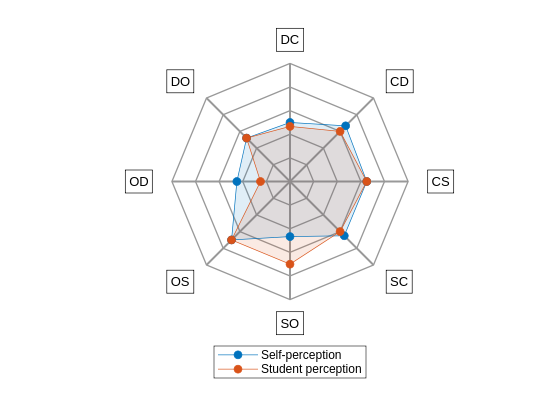

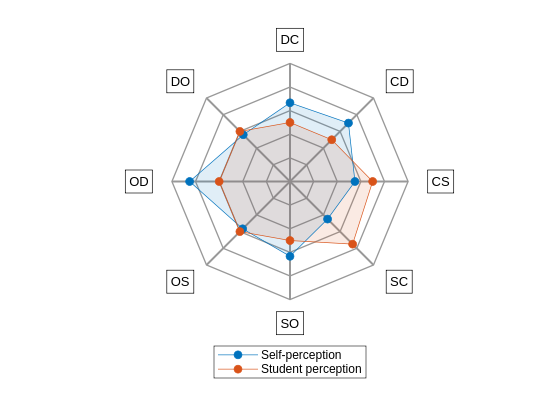

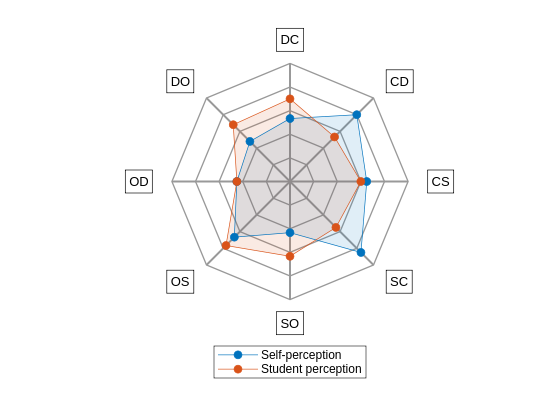

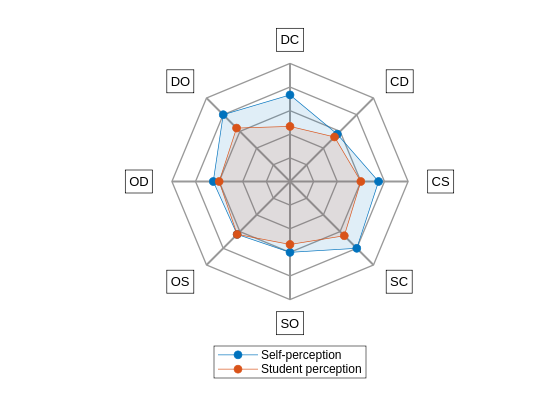

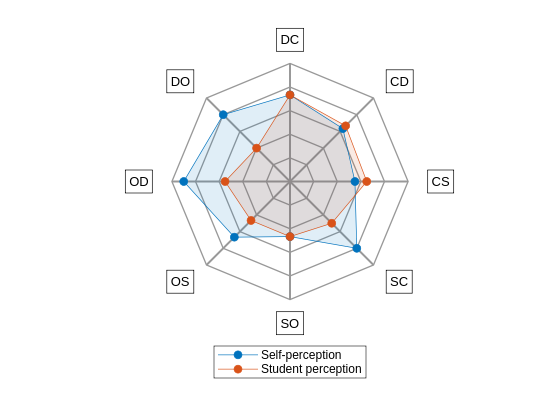

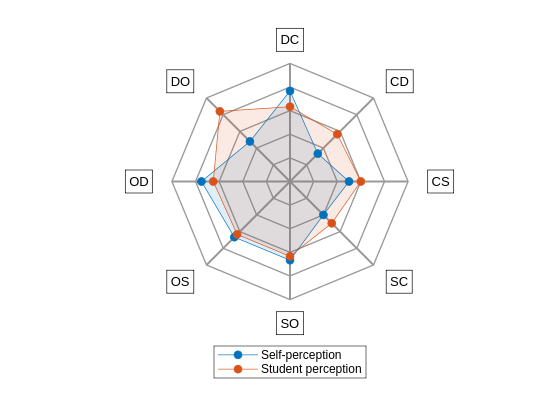

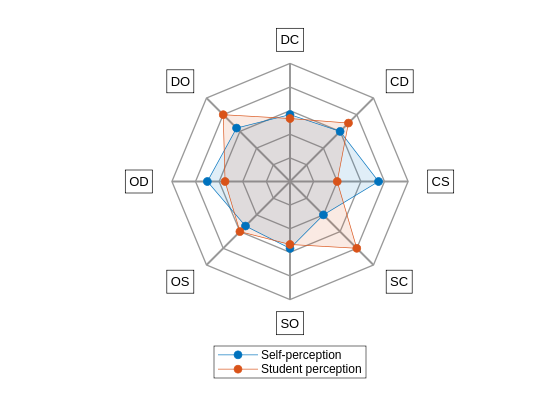

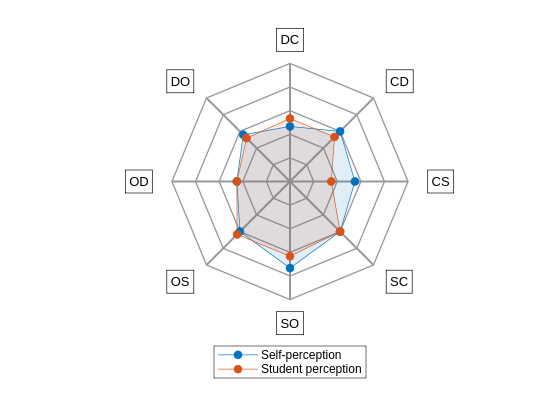

axes_limits = [ones(1,8)*1; ones(1,8)*5];
clf;close all;

for ii= 1:size(names,1)
    figure('Color','w');
    spider_plot_R2019b(S{ii}, ...
        'AxesLabels', scale_labels, ...
        'AxesInterval', 4, ...
        'AxesTickLabels', {'','','','',''},...
        'AxesPrecision', 1, ...
        'AxesLimits', axes_limits, ...
        'FillOption', 'on', ...
        'FillTransparency', 0.12, ...
        'LineWidth', 0.5);
    legend({'Self-perception','Student perception'}, 'Location','southoutside');
    exportgraphics(gcf,['./figures/spiderPlot_',names{ii,1},'_',names{ii,2},'.pdf'])
end

## Interpretation

Some examples:

**CD** reflects the helping/friendly scale. Both supervisor and student see the supervisor as generally friendly and supportive.

**DC** represents leadership. Both student (3.7) and supervisor (3.0) agree that the supervisor shows clear, structured leadership, with the student perceiving slightly stronger direction and confidence

**DO** represents strictness. Both agree that the supervisor is moderately strict (3.2 vs 2.8), maintaining expectations and standards without excessive rigidity.

**OD** represents admonishing. Both perceive the supervisor as only occasionally critical (3.25 vs 2.75), indicating feedback that is demanding but not hostile

**OS** represents dissatisfaction. The supervisor feels satisfied (2.0), while the student senses notable dissatisfaction (3.7), suggesting a communication gap in how approval or criticism is conveyed.

**SO** represents uncertainty. Both view the supervisor as somewhat uncertain (3.0 vs 3.5), possibly eflecting occasional ambiguity or mixed signals during discussions. 

**SC** represents the student’s responsibility/freedom. Both agree that autonomy is moderate (3.0 vs 2.5), showing a balance between independence and supervision, though the supervisor perceives granting slightly more freedom.

**CS** represents understanding. Both see the supervisor as understanding and attentive (4.0 vs 3.25), with generally positive and empathetic interactions, though the supervisor rates this more favorably.

## Automated interpretation with chatGPT prompt

ii = 1;
mode = 'feedback';   % choose 'academic' or 'feedback'

figure('Color','w');
spider_plot_R2019b(S{ii}, ...
    'AxesLabels', scale_labels, ...
    'AxesInterval', 4, ...
    'AxesTickLabels', {'','','','',''}, ...
    'AxesPrecision', 1, ...
    'AxesLimits', axes_limits, ...
    'FillOption', 'on', ...
    'FillTransparency', 0.12, ...
    'LineWidth', 0.5);
legend({'Self-perception','Student perception'}, 'Location','southoutside');

% Step 1: Postprocess QSDI data
[summaryTable, promptText] = postprocess_QSDI(S{ii}, scale_labels);
disp(summaryTable)

% Step 2: Build ChatGPT prompt text depending on mode
switch mode
    case 'academic'
        basePrompt = [
            "You are an expert in doctoral supervision research familiar with the QSDI model (Mainhard et al., 2009). ", ...
            "Interpret the following results for a supervisor–student pair. ", ...
            "A difference of 0.25 points or less is considered agreement (not significant). ", ...
            "Focus on patterns of agreement and meaningful differences to describe the interpersonal dynamic. ", ...
            "Keep the tone academic but concise (about 150–250 words).\n\n", ...
            ...
            "### Theoretical Context (Mainhard et al., 2009):\n", ...
            "The Questionnaire on Supervisor–Doctoral Student Interaction (QSDI) conceptualizes supervision as a two-dimensional interpersonal model: ", ...
            "the vertical axis represents **Influence** (dominance–submission), and the horizontal axis represents **Proximity** (cooperation–opposition). ", ...
            "These dimensions describe supervisors’ interpersonal styles, which together form eight sectors arranged in a circumplex model: ", ...
            "Leadership (DC), Helping/Friendly (CD), Understanding (CS), Student Responsibility/Freedom (SC), Uncertain (SO), Dissatisfied (OS), ", ...
            "Admonishing (OD), and Strict (DO). High Influence behaviors reflect direction, control, and confidence; high Proximity behaviors reflect warmth and cooperation. ", ...
            "Opposite sectors (e.g., Helping/Friendly vs. Dissatisfied) often represent inherent tensions between support and evaluation. ", ...
            "Complementary processes occur along Proximity (friendliness evokes friendliness), whereas reciprocal processes occur along Influence (dominance evokes submission). ", ...
            "Supervisor–student alignment across these scales is linked to satisfaction, progress, and supervision quality.\n\n", ...
            ...
            "### QSDI Scale Reference:\n", ...
            "DC = Leadership/directiveness (dominant–cooperative)\n", ...
            "CD = Helping/friendly (cooperative–dominant)\n", ...
            "CS = Understanding (cooperative–submissive)\n", ...
            "SC = Student responsibility/freedom (submissive–cooperative)\n", ...
            "SO = Uncertain (submissive–oppositional)\n", ...
            "OS = Dissatisfied (oppositional–submissive)\n", ...
            "OD = Admonishing (oppositional–dominant)\n", ...
            "DO = Strict (dominant–oppositional)\n\n", ...
            ...
            "### QSDI Results:\n", promptText, "\n\n", ...
            "### Task:\nSummarize the findings, highlight areas of agreement vs. disagreement, ", ...
            "and interpret what these patterns suggest about the supervisory relationship’s balance of structure, support, and communication."
        ];

    case 'feedback'
        basePrompt = [
            "You are an expert in doctoral supervision and professional development. ", ...
            "Interpret the following QSDI results for a supervisor–student pair. ", ...
            "A difference of 0.25 points or less means both agree on that aspect. ", ...
            "Differences greater than 0.25 indicate a meaningful perception gap that may need attention. ", ...
            "Your goal is to give **clear, constructive feedback** for the supervisor — not a research summary. ", ...
            "Write as if you are providing personalized, actionable insights during a feedback session. ", ...
            "Keep the tone professional, supportive, and practical (150–250 words).\n\n", ...
            ...
            "### Model background (summary):\n", ...
            "The QSDI describes eight styles of supervisory interaction, arranged around two dimensions: ", ...
            "**Influence** (how directive or confident the supervisor appears) and **Proximity** (how cooperative or distant the relationship feels). ", ...
            "The eight styles are:\n", ...
            "DC = Leadership/directiveness\n", ...
            "CD = Helping/Friendly\n", ...
            "CS = Understanding\n", ...
            "SC = Student Responsibility/Freedom\n", ...
            "SO = Uncertain\n", ...
            "OS = Dissatisfied\n", ...
            "OD = Admonishing\n", ...
            "DO = Strict\n\n", ...
            "High scores on cooperative scales (CD, CS, SC) show warmth and support. ", ...
            "High scores on oppositional scales (SO, OS, OD, DO) may reflect tension, confusion, or critical feedback.\n\n", ...
            ...
            "### QSDI Results:\n", promptText, "\n\n", ...
            ...
            "### Task:\n", ...
            "1. Highlight areas where supervisor and student perceptions differ (Δ > 0.25).\n", ...
            "2. Explain what those differences might mean in everyday supervision.\n", ...
            "3. Offer **specific, actionable suggestions** (e.g., communication habits, meeting structure, feedback clarity).\n", ...
            "4. End with a short summary on overall relationship quality and next steps.\n", ...
            "Optionally include a short bullet list titled 'Practical Actions' summarizing recommendations."
        ];
end

% Step 3: Print prompt for ChatGPT copy-paste
fprintf('\n\n================= COPY BELOW THIS LINE =================\n\n');
fprintf('%s\n', basePrompt);
fprintf('\n================= COPY ABOVE THIS LINE =================\n\n');



    Scale     Supervisor    Student    Difference       Status   
    ______    __________    _______    __________    ____________

    {'DC'}         2.5      2.3333      0.16667      "Agreement" 
    {'CD'}      3.3333           3      0.33333      "Difference"
    {'CS'}        3.25        3.25            0      "Agreement" 
    {'SC'}        3.25           3         0.25      "Agreement" 
    {'SO'}      2.3333         3.5       1.1667      "Difference"
    {'OS'}         3.5         3.5            0      "Agreement" 
    {'OD'}        2.25        1.25            1      "Difference"
    {'DO'}         2.6         2.6            0      "Agreement" 





================= COPY BELOW THIS LINE =================



You are an expert in doctoral supervision research familiar with the QSDI model (Mainhard et al., 2009). 
Interpret the following results for a supervisor–student pair. 
A difference of 0.25 points or less is considered agreement (not significant). 
Focus on patterns of agreement and meaningful differences to describe the interpersonal dynamic. 
Keep the tone academic but concise (about 150–250 words).\n\n
### Theoretical Context (Mainhard et al., 2009):\n
The Questionnaire on Supervisor–Doctoral Student Interaction (QSDI) conceptualizes supervision as a two-dimensional interpersonal model: 
the vertical axis represents **Influence** (dominance–submission), and the horizontal axis represents **Proximity** (cooperation–opposition). 
These dimensions describe supervisors’ interpersonal styles, which together form eight sectors arranged in a circumplex model: 
Leadership (DC), Helping/Friendly (CD), Understanding (CS), Student Responsibility/Freedom (SC), Uncertain (SO), Dissatisfied (OS)


================= COPY ABOVE THIS LINE =================

